## Create MATLAB Environment

Create a MATLAB® environment for the lander vehicle using the lander `LanderVehicle` class.

clear all
close all
clc

rlAgentLCParams

## Set the sampling time nad total simulation times

Agent operate at the same sample time in this example. Set the sample time value (in seconds).

Ts = 0.1;

%  set the simulation time
Tf = 15; % simulation time


## create the timeseries velocity vector

load('subjectOrg43.mat')
timeVec = Ts:Ts:Tf;
timeVecOrg = Ts:Ts:60-Ts; % the NGSIM data is for 59 sec
vSub = subjectOrg43(:,12);
indx = ceil(linspace(1,length(vSub),Tf/Ts));

vSubRed = vSub(indx)

vSubRed =     4.5720
    4.4196
    3.2004
    3.0480
    3.0480
    3.0510
    2.6792
    1.9507
    1.8044
    1.8806


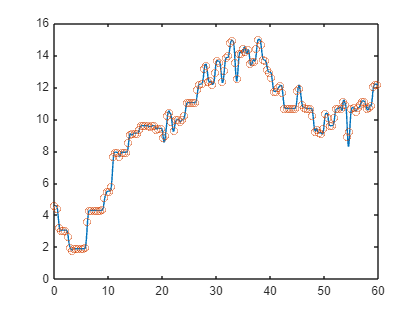

plot(timeVecOrg, vSub)
hold on
plot(timeVecOrg(indx), vSubRed, 'O')


vSubTimeSeries = timeseries(vSubRed, timeVec);


Open the Simulink model.

mdl = "rlAgentLCLatVaryingVx";
open_system(mdl)

Create the observation and action specifications for lateral control loop.

obsInfo1 = rlNumericSpec([4 1]);
actInfo1 = rlFiniteSetSpec((-10:0.01:10));

Combine the observation and action specifications as a cell array.

obsInfo = obsInfo1;
actInfo = actInfo1;

Create a Simulink environment interface, specifying the block paths for both agent blocks. The order of the block paths must match the order of the observation and action specification cell arrays.

blks = mdl + ["/RL Agent1"];
env = rlSimulinkEnv(mdl,blks,obsInfo,actInfo);

Specify a reset function for the environment using the `ResetFcn` property. The function `pfcResetFcn` randomly sets the initial poses of the lead and ego vehicles at the beginning of every episode during training.

env.ResetFcn = @pfcResetFcn;

The training can be sensitive to the initial network weights and biases, and results can vary with different sets of values. The network weights are randomly initialized to small values in this example. Ensure reproducibility by fixing the seed of the random generator.

rng(0)

## Create PPO Agent

PPO agents use a parametrized value function approximator to estimate the value of the policy. A value-function critic takes the current observation as input and returns a single scalar as output (the estimated discounted cumulative long-term reward for following the policy from the state corresponding to the current observation). 

To model the parametrized value function within the critic, use a neural network with one input layer (which receives the content of the observation channel, as specified by `obsInfo`) and one output layer (which returns the scalar value). Note that `prod(obsInfo.Dimension)` returns the total number of dimensions of the observation space regardless of whether the observation space is a column vector, row vector, or matrix.

numObs = prod(obsInfo.Dimension);
criticLayerSizes = [400 300];
actorLayerSizes = [400 300];

Define the network as an array of layer objects.

criticNetwork = [
    featureInputLayer(numObs)
    fullyConnectedLayer(criticLayerSizes(1), ...
        Weights=sqrt(2/numObs)*...
            (rand(criticLayerSizes(1),numObs)-0.5), ...
        Bias=1e-3*ones(criticLayerSizes(1),1))
    reluLayer
    fullyConnectedLayer(criticLayerSizes(2), ...
        Weights=sqrt(2/criticLayerSizes(1))*...
            (rand(criticLayerSizes(2),criticLayerSizes(1))-0.5), ...
        Bias=1e-3*ones(criticLayerSizes(2),1))
    reluLayer
    fullyConnectedLayer(criticLayerSizes(2), ...
        Weights=sqrt(2/criticLayerSizes(2))*...
            (rand(criticLayerSizes(2),criticLayerSizes(2))-0.5), ...
        Bias=1e-3*ones(criticLayerSizes(2),1))
    reluLayer
    fullyConnectedLayer(1, ...
        Weights=sqrt(2/criticLayerSizes(2))* ...
            (rand(1,criticLayerSizes(2))-0.5), ...
        Bias=1e-3)
    ];

Convert to `dlnetwork` and display the number of weights.

criticNetwork = dlnetwork(criticNetwork);
summary(criticNetwork)

   Initialized: true

   Number of learnables: 212.9k

   Inputs:
      1   'input'   4 features



Create the critic approximator object using `criticNet` and the observation specification. For more information on value function approximators, see [`rlValueFunction`](docid:rl_ref#mw_18117070-1c6d-40ba-91f0-0f2cd337918a).

critic = rlValueFunction(criticNetwork,obsInfo);

Policy gradient agents use a parametrized stochastic policy, which for discrete action spaces is implemented by a discrete categorical actor. This actor takes an observation as input and returns as output a random action sampled (among the finite number of possible actions) from a categorical probability distribution. 

To model the parametrized policy within the actor, use a neural network with one input layer (which receives the content of the environment observation channel, as specified by `obsInfo`) and one output layer. The output layer must return a vector of probabilities for each possible action, as specified by `actInfo`. Note that `numel(actInfo.Dimension)` returns the number of elements of the discrete action space.

Define the network as an array of layer objects.

actorNetwork = [
    featureInputLayer(numObs)
    fullyConnectedLayer(actorLayerSizes(1), ...
        Weights=sqrt(2/numObs)*...
            (rand(actorLayerSizes(1),numObs)-0.5), ...
        Bias=1e-3*ones(actorLayerSizes(1),1))
    reluLayer
    fullyConnectedLayer(actorLayerSizes(2), ...
        Weights=sqrt(2/actorLayerSizes(1))*...
            (rand(actorLayerSizes(2),actorLayerSizes(1))-0.5), ...
        Bias=1e-3*ones(actorLayerSizes(2),1))
    reluLayer
    fullyConnectedLayer(actorLayerSizes(2), ...
        Weights=sqrt(2/actorLayerSizes(2))*...
            (rand(actorLayerSizes(2),actorLayerSizes(2))-0.5), ...
        Bias=1e-3*ones(actorLayerSizes(2),1))
    reluLayer
    fullyConnectedLayer(numel(actInfo.Elements), ...
        Weights=sqrt(2/actorLayerSizes(2))*...
            (rand(numel(actInfo.Elements),actorLayerSizes(2))-0.5), ...
        Bias=1e-3*ones(numel(actInfo.Elements),1))
    softmaxLayer
    ];

Convert to `dlnetwork` and display the number of weights.

actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 814.9k

   Inputs:
      1   'input'   4 features



Create the actor using `actorNet` and the observation and action specifications. For more information on discrete categorical actors, see [`rlDiscreteCategoricalActor`](docid:rl_ref#mw_21bebe76-ad01-4680-9c10-59fd51f224b6).

actor = rlDiscreteCategoricalActor(actorNetwork,obsInfo,actInfo);

Specify training options for the critic and the actor using [`rlOptimizerOptions`](docid:rl_ref#mw_18a712bb-b821-4dd9-a7ad-460ad7f2aa03).

actorOpts = rlOptimizerOptions(LearnRate=1e-3);
criticOpts = rlOptimizerOptions(LearnRate=1e-3);

Specify the agent hyperparameters using an `rlPPOAgentOptions` object, include the training options for the actor and critic.

agentOpts = rlPPOAgentOptions(...
    ExperienceHorizon=ceil(Tf/Ts),...
    ClipFactor=0.02,...
    EntropyLossWeight=0.01,...
    ActorOptimizerOptions=actorOpts,...
    CriticOptimizerOptions=criticOpts,...
    NumEpoch=10,...
    AdvantageEstimateMethod="gae",...
    GAEFactor=0.95,...
    SampleTime=0.1,...
    DiscountFactor=0.997);

For these hyperparameters:

- The agent collects experiences until it reaches the experience horizon of 600 steps or episode termination and then trains from mini-batches of 128 experiences for 3 epochs. 

- For improving training stability, use an objective function clip factor of 0.02. 

- A discount factor value of 0.997 promotes long term rewards. 

- Variance in critic output is reduced by using the Generalized Advantage Estimate method with a GAE factor of 0.95. 

- The `EntropyLossWeight` term of 0.01 enhances exploration during training.

Create the PPO agent.

agent = rlPPOAgent(actor,critic,agentOpts);

Alternatively, you can create the agent first, and then access its option object and modify the options using dot notation.

## Train Agent

To train the PPO agent, specify the following training options.

- Run the training for at most 20000 episodes, with each episode lasting at most 600 time steps.

- Stop the training when the average reward over 100 consecutive episodes is 450 or more.

trainOpts = rlTrainingOptions(...
    MaxEpisodes=5000,...
    MaxStepsPerEpisode=ceil(Tf/Ts),...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=0,...
    ScoreAveragingWindowLength=100);

Train the agent using the `train` function. Due to the complexity of the environment, training process is computationally intensive and takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`.

doTraining = true;
if doTraining   
    trainingStats = train(agent, env, trainOpts);
else
    load("landerVehicleAgent.mat");
end

Invalid or deleted object.

Error in rl.internal.episodeManager.OnlineEpisodeManager/stop (line 242)
            if ~this.IsClosed && ~this.IsStopped

Error in rl.internal.trainmgr.OnlineTrainingManager/run_ (<a href="matlab: opentoline('C:\Program Files\MATLAB\R2024a\toolbox\rl\rl\+rl\+internal\+trainmgr\OnlineTrainingManager.m',116,0)">line 116</

An example training session is shown below. The actual results may vary because of randomness in the training process.

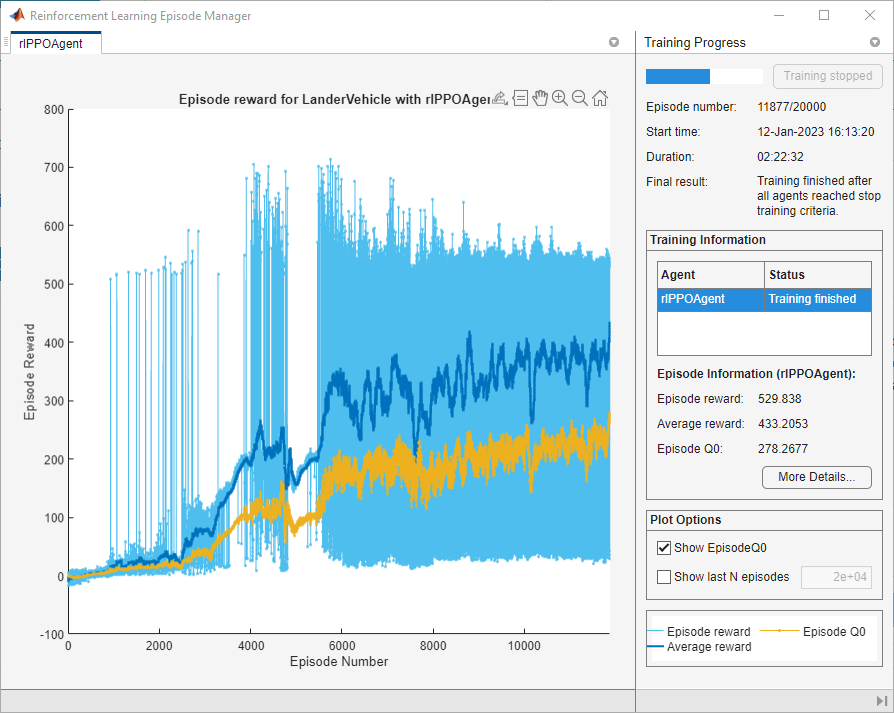

## Simulate

Plot the environment first to create a visualization for the lander vehicle.

plot(env)

Set the random seed for simulation reproducibility.

rng(10)

Set up simulation options to perform 5 simulations. For more information see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2).

simOptions = rlSimulationOptions(MaxSteps=600);
simOptions.NumSimulations = 5;

Simulate the trained agent within the environment. For more information see [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

experience = sim(env, agent, simOptions);

Plot the time history of the states for all simulations using the helper function `plotLanderVehicleTrajectory` provided in the example folder.

% Observations to plot
obsToPlot = ["x", "y", "dx", "dy", "theta", "dtheta", "landing"];

% Create a figure
f = figure();
f.Position(3:4) = [800,1000];

% Create a tiled layout for the plots
t = tiledlayout(f, 4, 2, TileSpacing="compact");

% Plot the data
for ct = 1:numel(obsToPlot)
    ax = nexttile(t);
    plotLanderVehicleTrajectory(ax, experience, env, obsToPlot(ct));
end

*Copyright 2019-2023 The MathWorks, Inc.*